%% clear workspace
clear variables
close all
clc

## load in data

addpath(genpath('C:\Users\Xiangnan\Documents\MyGitRepo\FLImBrushDataProcessingTool\Preprocessing_APD'))
FB = load('C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\Decon 10GS 154ns 0.9619\20210722DyeTest2_03.mat');
FBDC = load('C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\Decon 10GS 154ns 0.9619 DC moving avg tail\20210722DyeTest2_03.mat');
FBCh3 = load('C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\Decon 10GS 154ns 0.9619\20210722DyeTest2_05.mat');
FBDCCh3 = load('C:\Users\Xiangnan\Box Sync\FLImBrush vs V4\20210722V4vsFLImBRUSHDye\FLImBRUSH\20210722DyeTest2\Decon 10GS 154ns 0.9619 DC moving avg tail\20210722DyeTest2_05.mat');

## plot iRF

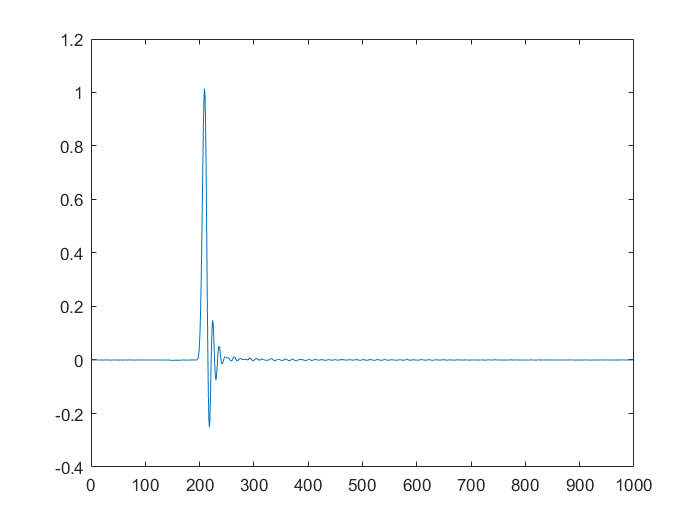

irf1 = FB.Ch1DataObj.APDObj.irf;
figure
plot(irf1(:,210))

## plot raw data

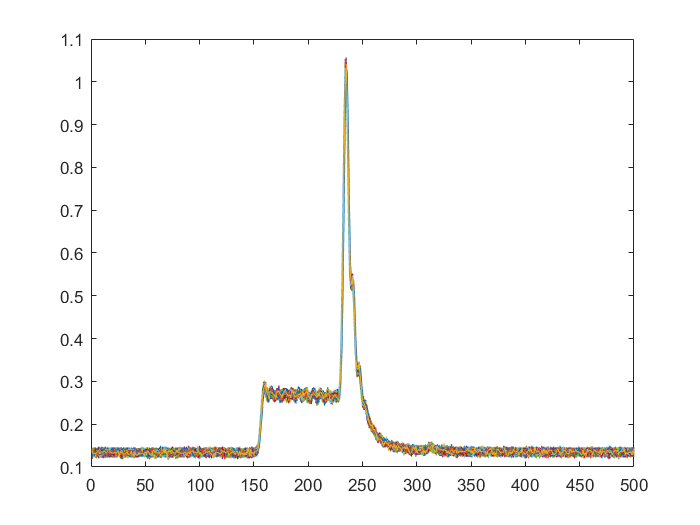

rawData1 = FBDC.Ch1DataObj.rawData;
figure;plot(rawData1)

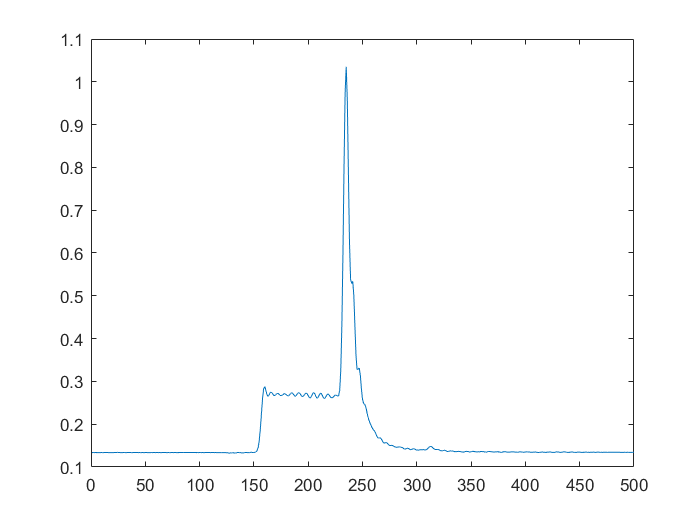

figure;plot(mean(rawData1,2))

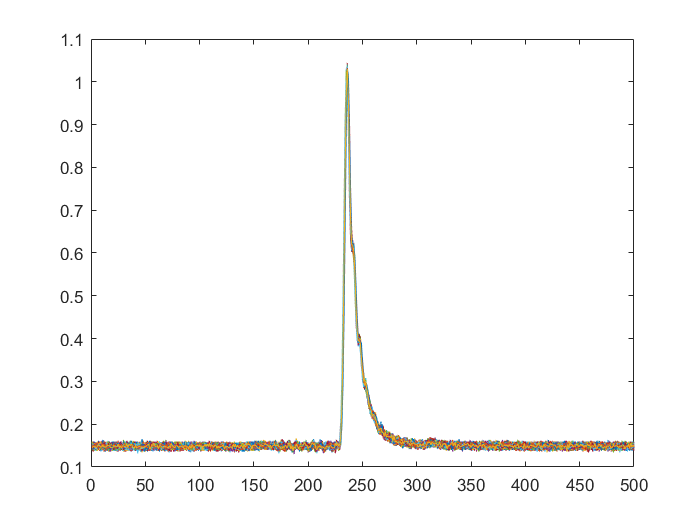

rawData2 = FBDC.Ch2DataObj.rawData;
figure;plot(rawData2)

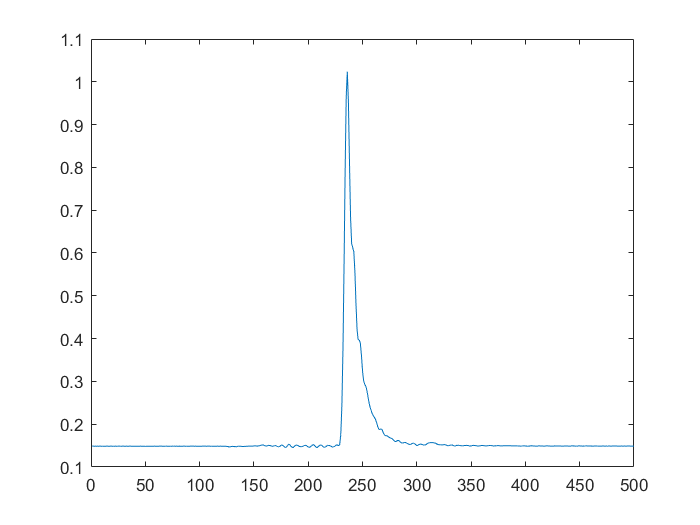

figure;plot(mean(rawData2,2))

## lifetime violin

FBLT1 = FB.Ch1DataObj.LTs;
FBLT2 = FB.Ch2DataObj.LTs;
FBLT3 = FBCh3.Ch3DataObj.LTs;
FBDCLT1 = FBDC.Ch1DataObj.LTs;
FBDCLT2 = FBDC.Ch2DataObj.LTs;
FBDCLT3 = FBDCCh3.Ch3DataObj.LTs;
FBAll = [FBLT1 FBLT2 FBLT3(1:195)];
FBDCAll = [FBDCLT1 FBDCLT2 FBDCLT3(1:195)];


## plot

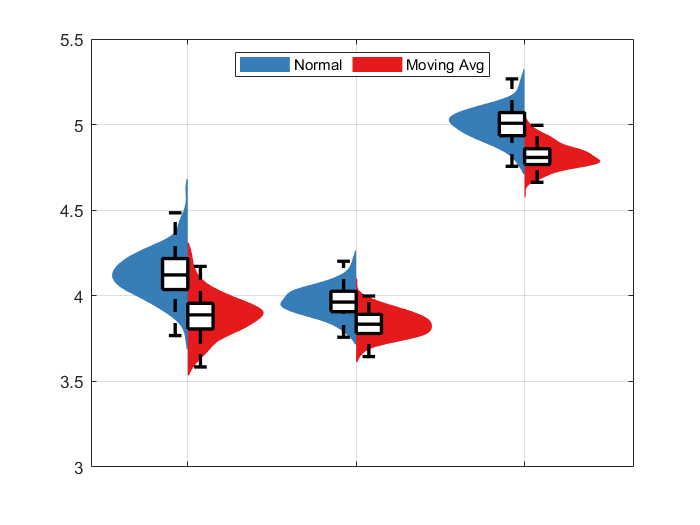

figure
violinbox(FBAll,FBDCAll,1,1,[])
grid on
ylim([3 5.5])
legend('Normal','Moving Avg')

## plot channel 1 DC

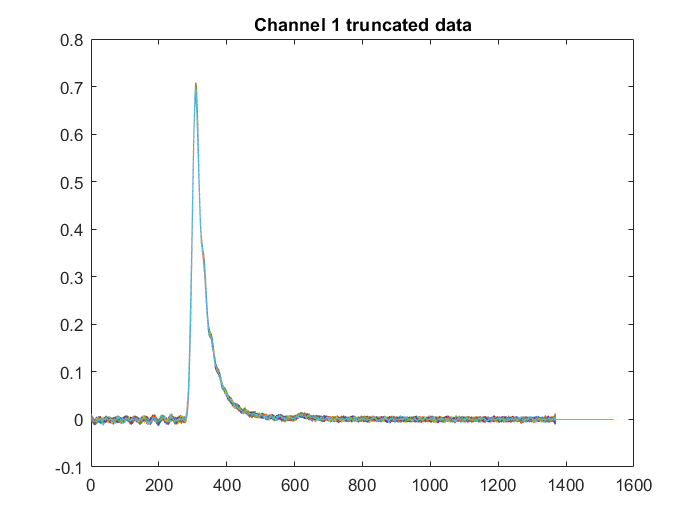

data1 = FBDC.Ch1DataObj.dataT;
figure;plot(data1);title('Channel 1 truncated data')

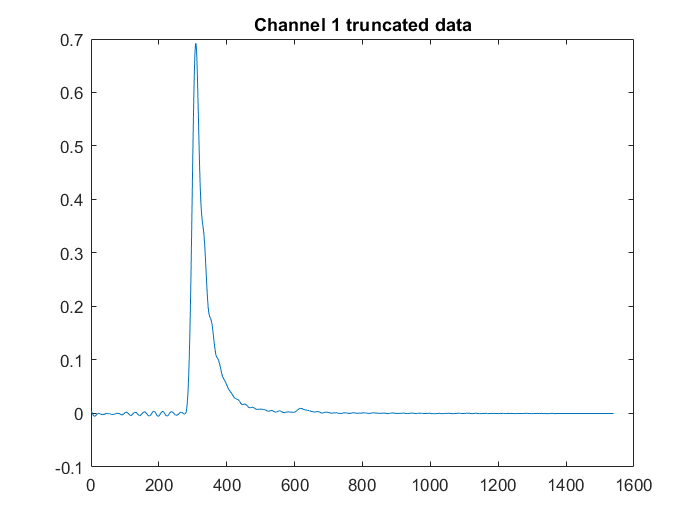

figure;plot(mean(data1,2));title('Channel 1 truncated data')

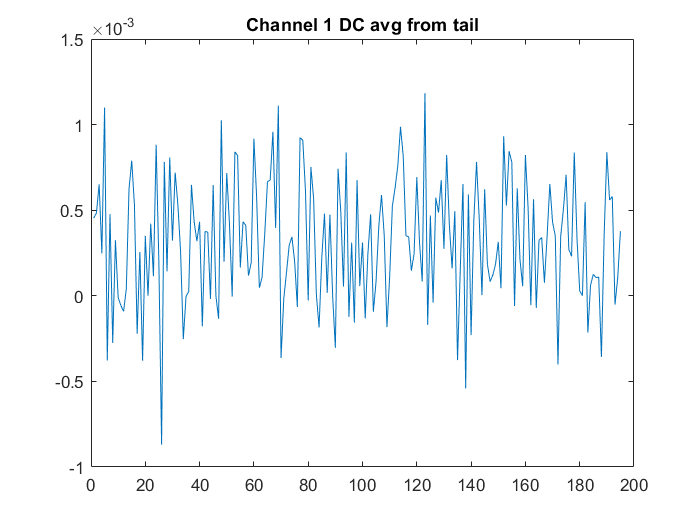

% figure;plot(mean(data1(1:200,:)))
% title('Channel 1 DC avg from start')
dataTemp1 = data1(900:1000,:);
figure;plot(mean(dataTemp1))
title('Channel 1 DC avg from tail')

mean(mean(dataTemp1))

ans = 3.1808e-04

## plot channel 2 DC

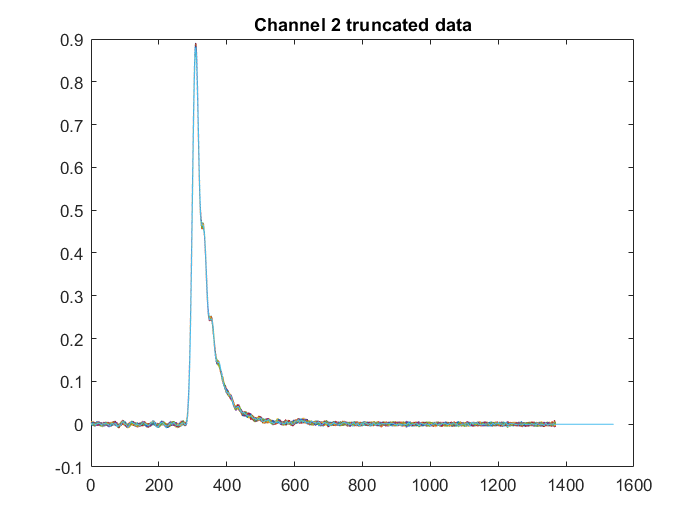

data2 = FBDC.Ch2DataObj.dataT;
figure;plot(data2);title('Channel 2 truncated data')

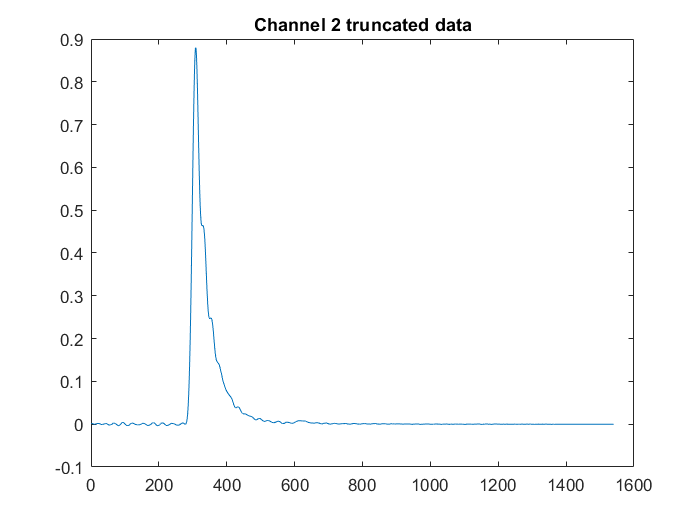

figure;plot(mean(data2,2));title('Channel 2 truncated data')

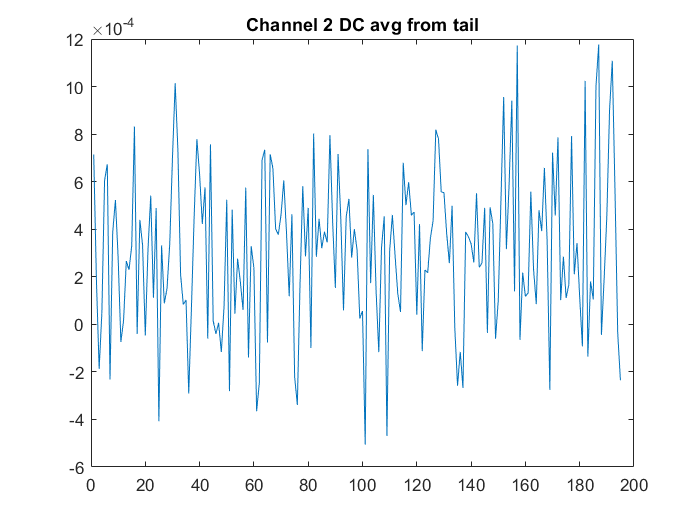

% figure;plot(mean(data2(1:200,:)))
% title('Channel 2 DC avg from start')
dataTemp2 = data2(900:1000,:);
figure;plot(mean(dataTemp2))
title('Channel 2 DC avg from tail')

mean(mean(dataTemp2))

ans = 3.0914e-04